% generate_phase1_figures.m
%
% Script to generate key figures for Phase 1:
% Data Setup, Preprocessing, Splitting, and Outlier Detection.
% Adheres to specified plotting guidelines.
%
% Date: 2025-05-17 (Corrected data loading logic and conditional plotting)

%% 0. Initialization & Setup
% =========================================================================
clear; clc; close all;
fprintf('Generating Phase 1 Dissertation Figures - %s\n', string(datetime('now')));

Generating Phase 1 Dissertation Figures - 17-May-2025 08:22:44



% --- Define Paths ---
projectRoot = pwd; 
if ~exist(fullfile(projectRoot, 'src'), 'dir') || ~exist(fullfile(projectRoot, 'data'), 'dir')
    error(['Project structure not found. Please ensure MATLAB''s "Current Folder" is set to your ' ...
           'main project root directory. Current directory is: %s'], projectRoot);
end

dataPath      = fullfile(projectRoot, 'data');
figuresPath   = fullfile(projectRoot, 'figures', 'Phase1_Dissertation_Plots');
if ~exist(figuresPath, 'dir'), mkdir(figuresPath); end
dateStrForFilenames = string(datetime('now','Format','yyyyMMdd'));

% --- Plotting Defaults ---
plotFontSize = 12;
plotXLabel = 'Wellenzahl (cm^{-1})';
plotYLabelAbsorption = 'Absorption (a.u.)';
plotXLim = [950 1800];
colorWHO1 = [0.9, 0.6, 0.4]; 
colorWHO3 = [0.4, 0.702, 0.902]; 
colorOutlier = [0.8, 0, 0]; 

%% 1. Load Wavenumbers (Essential for all spectral plots)
% =========================================================================
fprintf('Loading wavenumbers...\n');

Loading wavenumbers...


try
    wavenumbers_data = load(fullfile(dataPath, 'wavenumbers.mat'), 'wavenumbers_roi');
    wavenumbers_roi = wavenumbers_data.wavenumbers_roi;
    if iscolumn(wavenumbers_roi), wavenumbers_roi = wavenumbers_roi'; end
    num_wavenumber_points = length(wavenumbers_roi);
catch ME
    fprintf('ERROR loading wavenumbers.mat: %s\n', ME.message); 
    fprintf('This file is essential. Please ensure it is in the %s directory.\n', dataPath);
    return;
end

%% FIGURE 1: Effect of Sequential Preprocessing Steps on Two Representative Probes/Positions
% Loads from dataTable.CombinedRawSpectra (from data_table_complete.mat)
% =====================================================================================
fprintf('\n--- Attempting to generate Figure 1: Effect of Sequential Preprocessing Steps ---\n');


--- Attempting to generate Figure 1: Effect of Sequential Preprocessing Steps ---



example_probe_row_idx_1 = 1;  % <<<< ADAPT THIS from dataTable
example_probe_row_idx_2 = 2;  % <<<< ADAPT THIS from dataTable

spec_data_fig1 = struct(); 
fig1_data_processed_successfully = false; 
sg_poly_order_fig1 = 2; 
sg_frame_len_fig1 = 11; 

try
    fprintf('Loading dataTable from data_table_complete.mat for Figure 1...\n');
    loadedDataTableComplete = load(fullfile(dataPath, 'data_table_complete.mat'), 'dataTable');
    if ~isfield(loadedDataTableComplete, 'dataTable')
        error('Variable "dataTable" not found in data_table_complete.mat.');
    end
    dataTableFullFig1 = loadedDataTableComplete.dataTable;
    fprintf('"dataTable" for Figure 1 loaded with %d entries.\n', height(dataTableFullFig1));

    if example_probe_row_idx_1 > height(dataTableFullFig1) || example_probe_row_idx_2 > height(dataTableFullFig1) || ...
       example_probe_row_idx_1 < 1 || example_probe_row_idx_2 < 1 || ...
       example_probe_row_idx_1 == example_probe_row_idx_2
        error(['Invalid example_probe_row_idx_1 (%d) or example_probe_row_idx_2 (%d). ' ...
               'Choose valid, distinct row indices from dataTable (max %d).'], ...
               example_probe_row_idx_1, example_probe_row_idx_2, height(dataTableFullFig1));
    end
    
    probeFieldsFig1 = {'Probe1', 'Probe2'};
    example_indices_fig1 = [example_probe_row_idx_1, example_probe_row_idx_2];

    for pf_idx = 1:length(probeFieldsFig1)
        currentProbeStructField = probeFieldsFig1{pf_idx};
        currentRowIdx = example_indices_fig1(pf_idx);
        
        temp_label_parts = {};
        if ismember('Diss_ID', dataTableFullFig1.Properties.VariableNames) && iscell(dataTableFullFig1.Diss_ID) && length(dataTableFullFig1.Diss_ID) >= currentRowIdx
            temp_label_parts{end+1} = dataTableFullFig1.Diss_ID{currentRowIdx};
        end
        if ismember('Position', dataTableFullFig1.Properties.VariableNames) && iscell(dataTableFullFig1.Position) && length(dataTableFullFig1.Position) >= currentRowIdx
             temp_label_parts{end+1} = dataTableFullFig1.Position{currentRowIdx};
        end
        spec_data_fig1.(currentProbeStructField).Label = strjoin(temp_label_parts, ' ');
        if isempty(spec_data_fig1.(currentProbeStructField).Label), spec_data_fig1.(currentProbeStructField).Label = sprintf('Probe Row %d', currentRowIdx); end

        if ~ismember('CombinedRawSpectra', dataTableFullFig1.Properties.VariableNames) || ~iscell(dataTableFullFig1.CombinedRawSpectra)
            error('dataTable.CombinedRawSpectra column missing or not a cell array.');
        end
        spec_data_fig1.(currentProbeStructField).S0_Original = dataTableFullFig1.CombinedRawSpectra{currentRowIdx};
        if isempty(spec_data_fig1.(currentProbeStructField).S0_Original) || size(spec_data_fig1.(currentProbeStructField).S0_Original, 2) ~= num_wavenumber_points
            error('CombinedRawSpectra for %s (Row %d) empty or wrong wavenumber dim. Expected %d, got %d.', ...
                spec_data_fig1.(currentProbeStructField).Label, currentRowIdx, num_wavenumber_points, size(spec_data_fig1.(currentProbeStructField).S0_Original, 2));
        end
        spec_data_fig1.(currentProbeStructField).NumSpectra = size(spec_data_fig1.(currentProbeStructField).S0_Original, 1);
        
        temp_s0 = spec_data_fig1.(currentProbeStructField).S0_Original;
        temp_s1 = zeros(size(temp_s0));
        for j = 1:size(temp_s0, 1), spectrum_j = temp_s0(j,:); if length(spectrum_j) >= sg_frame_len_fig1 && ~all(isnan(spectrum_j)), try temp_s1(j,:) = sgolayfilt(spectrum_j, sg_poly_order_fig1, sg_frame_len_fig1); catch; temp_s1(j,:) = spectrum_j; end; else; temp_s1(j,:) = spectrum_j; end; end
        spec_data_fig1.(currentProbeStructField).S1_Smoothed = temp_s1;
        temp_s2 = zeros(size(temp_s1));
        for j = 1:size(temp_s1, 1), spec_to_snv = temp_s1(j,:); if ~all(isnan(spec_to_snv)) && ~all(spec_to_snv == 0,'all'), mean_val_s1 = mean(spec_to_snv, 2, 'omitnan'); std_val_s1 = std(spec_to_snv, 0, 2, 'omitnan'); if std_val_s1 >= eps, temp_s2(j,:) = (spec_to_snv - mean_val_s1) / std_val_s1; else, temp_s2(j,:) = spec_to_snv; end; else; temp_s2(j,:) = spec_to_snv; end; end
        spec_data_fig1.(currentProbeStructField).S2_SNV = temp_s2;
        temp_s3 = zeros(size(temp_s2));
        for j = 1:size(temp_s2, 1), spec_to_l2 = temp_s2(j,:); if ~all(isnan(spec_to_l2)) && ~all(spec_to_l2 == 0,'all'), norm_val_s2 = norm(spec_to_l2, 2); if abs(norm_val_s2) >= eps, temp_s3(j,:) = spec_to_l2 / norm_val_s2; else, temp_s3(j,:) = spec_to_l2; end; else; temp_s3(j,:) = spec_to_l2; end; end
        spec_data_fig1.(currentProbeStructField).S3_L2Norm = temp_s3;
        fprintf('Preprocessing for Fig1 %s (%d spectra) complete.\n', spec_data_fig1.(currentProbeStructField).Label, spec_data_fig1.(currentProbeStructField).NumSpectra);
    end
    fig1_data_processed_successfully = true;
catch ME_fig1
    fprintf('ERROR during data loading or preprocessing for Figure 1: %s\n', ME_fig1.message);
    disp(ME_fig1.getReport);
end

Loading dataTable from data_table_complete.mat for Figure 1...


"dataTable" for Figure 1 loaded with 115 entries.


Preprocessing for Fig1 MEN-001-01 (768 spectra) complete.
Preprocessing for Fig1 MEN-002-01 (768 spectra) complete.


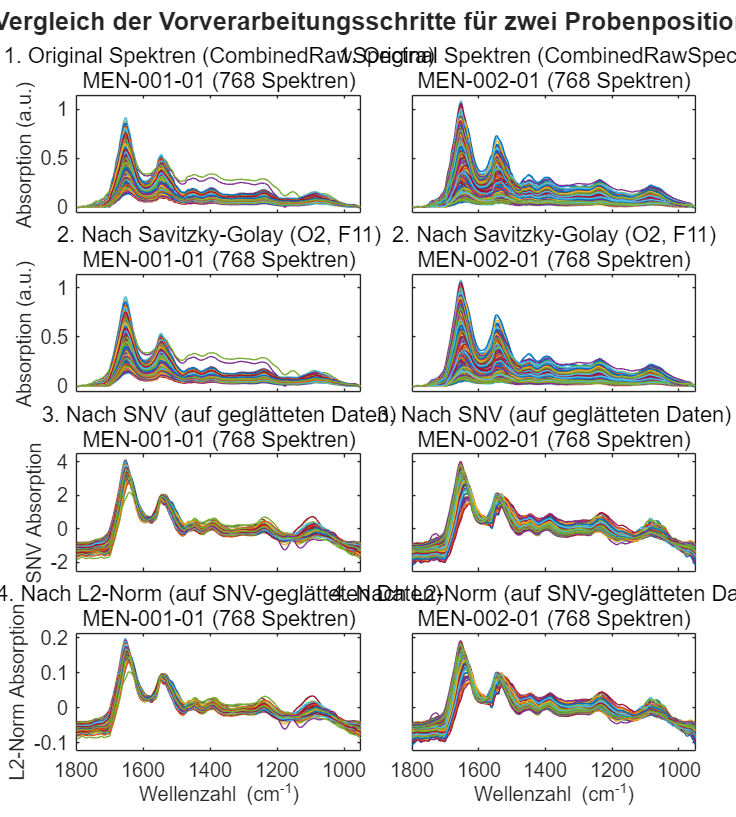

Figure 1 (Preprocessing Comparison) saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\Phase1_Dissertation_Plots\20250517_P1_Fig1_PreprocessingComparison.tiff



if fig1_data_processed_successfully
    fig1_handle = figure('Name', 'Effekt Sequenzieller Vorverarbeitungsschritte auf Proben');
    fig1_handle.Position = [50, 50, 900, 1000]; 
    t_f1 = tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    overall_title_fig1 = 'Vergleich der Vorverarbeitungsschritte für zwei Probenpositionen';
    title(t_f1, overall_title_fig1, 'FontSize', plotFontSize+2, 'FontWeight', 'bold');
    plot_stage_titles_base_fig1 = {'1. Original Spektren (CombinedRawSpectra)'; sprintf('2. Nach Savitzky-Golay (O%d, F%d)', sg_poly_order_fig1, sg_frame_len_fig1); '3. Nach SNV (auf geglätteten Daten)'; '4. Nach L2-Norm (auf SNV-geglätteten Daten)'};
    plot_stage_ylabels_fig1 = {plotYLabelAbsorption; plotYLabelAbsorption; 'SNV Absorption'; 'L2-Norm Absorption'};
    data_fields_ordered_fig1 = {'S0_Original', 'S1_Smoothed', 'S2_SNV', 'S3_L2Norm'};

    for stage_idx = 1:4 
        current_data_field_name = data_fields_ordered_fig1{stage_idx};
        y_data_stage_all_probes_fig1 = []; 
        temp_p1_data_fig1 = spec_data_fig1.Probe1.(current_data_field_name);
        if ~isempty(temp_p1_data_fig1), y_data_stage_all_probes_fig1 = [y_data_stage_all_probes_fig1; temp_p1_data_fig1(:)]; end
        temp_p2_data_fig1 = spec_data_fig1.Probe2.(current_data_field_name);
        if ~isempty(temp_p2_data_fig1), y_data_stage_all_probes_fig1 = [y_data_stage_all_probes_fig1; temp_p2_data_fig1(:)]; end
        common_y_lim_stage_fig1 = [];
        if ~isempty(y_data_stage_all_probes_fig1)
            min_y_s = min(y_data_stage_all_probes_fig1); max_y_s = max(y_data_stage_all_probes_fig1);
            pad_y_s = (max_y_s - min_y_s) * 0.05;
            if pad_y_s == 0, pad_y_s = abs(max_y_s * 0.1); if pad_y_s == 0, pad_y_s = 0.1; end; end
            common_y_lim_stage_fig1 = [min_y_s - pad_y_s, max_y_s + pad_y_s];
            if common_y_lim_stage_fig1(1) == common_y_lim_stage_fig1(2), common_y_lim_stage_fig1(2) = common_y_lim_stage_fig1(1)+eps; end
        end
        for probe_col_idx = 1:2 
            ax = nexttile((stage_idx-1)*2 + probe_col_idx );
            currentProbeStructField = probeFieldsFig1{probe_col_idx};
            current_spectra_to_plot = spec_data_fig1.(currentProbeStructField).(current_data_field_name);
            probe_label_for_title = spec_data_fig1.(currentProbeStructField).Label;
            num_spectra_for_title = spec_data_fig1.(currentProbeStructField).NumSpectra;
            if ~isempty(current_spectra_to_plot) && size(current_spectra_to_plot,2) == num_wavenumber_points
                plot(ax, wavenumbers_roi, current_spectra_to_plot', 'LineWidth', 0.5); 
            else text(0.5,0.5, 'Keine Spektren', 'Parent', ax, 'HorizontalAlignment','center', 'FontSize', plotFontSize-2); end
            title(ax, {plot_stage_titles_base_fig1{stage_idx}; sprintf('%s (%d Spektren)', probe_label_for_title, num_spectra_for_title)}, 'FontSize', plotFontSize-2, 'FontWeight', 'normal', 'Interpreter', 'none');
            set(ax, 'XDir','reverse', 'XLim', plotXLim, 'FontSize', plotFontSize-1);
            grid(ax, 'off'); 
            if probe_col_idx == 1, ylabel(ax, plot_stage_ylabels_fig1{stage_idx}, 'FontSize', plotFontSize-1);
            else, set(ax, 'YTickLabel', []); end
            if stage_idx < 4, set(ax, 'XTickLabel', []);
            else, xlabel(ax, plotXLabel, 'FontSize', plotFontSize-1); end
            if ~isempty(common_y_lim_stage_fig1), ylim(ax, common_y_lim_stage_fig1); end
        end
    end
    figName_P1_F1 = fullfile(figuresPath, sprintf('%s_P1_Fig1_PreprocessingComparison.tiff', dateStrForFilenames));
    exportgraphics(fig1_handle, figName_P1_F1, 'Resolution', 300);
    fprintf('Figure 1 (Preprocessing Comparison) saved to: %s\n', figName_P1_F1);
    savefig(fig1_handle, strrep(figName_P1_F1, '.tiff', '.fig'));
else
    fprintf('Skipping Figure 1: Preprocessing comparison plot due to data loading or processing issues.\n');
end


Loading cleaned training data (training_set_no_outliers_T2Q.mat) for Fig 2...


Cleaned training data loaded for Fig 2: 30613 spectra, 441 features.


Generating Figure 2: Mean Spectra (WHO-1, WHO-3 separate) & Difference (Cleaned Training Data)...


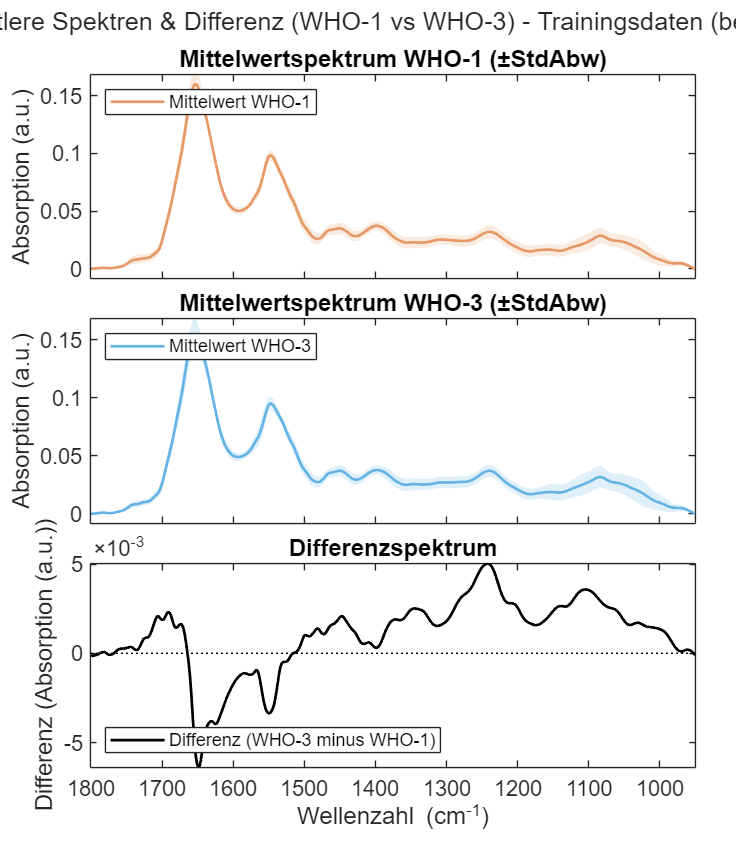

Figure 2 (Mean Spectra Separate & Difference) saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\Phase1_Dissertation_Plots\20250517_P1_Fig2_MeanDiffSpectra_SeparateCleaned.tiff



%% ---- FIGURE 2: Mean Spectra (WHO-1, WHO-3 separate) & Difference Spectrum ----
% Uses X_train_cleaned_fig2, y_train_numeric_cleaned_fig2, wavenumbers_roi
% Adds vertical grid lines to the plots.
%=========================================================================
% (The data loading part for X_train_cleaned_fig2 and y_train_numeric_cleaned_fig2 remains the same)
% if data_cleaned_loaded_fig2 ... (from previous version)

if data_cleaned_loaded_fig2 % This flag is set if X_train_cleaned_fig2 was loaded successfully
    fprintf('Generating Figure 2: Mean Spectra (WHO-1, WHO-3 separate) & Difference (Cleaned Training Data) with Vertical Grid...\n');
    
    mean_spec_WHO1_c = []; std_spec_WHO1_c = [];
    mean_spec_WHO3_c = []; std_spec_WHO3_c = [];

    if any(y_train_numeric_cleaned_fig2==1)
        mean_spec_WHO1_c = mean(X_train_cleaned_fig2(y_train_numeric_cleaned_fig2==1, :), 1);
        std_spec_WHO1_c = std(X_train_cleaned_fig2(y_train_numeric_cleaned_fig2==1, :), 0, 1);
    end
    if any(y_train_numeric_cleaned_fig2==3)
        mean_spec_WHO3_c = mean(X_train_cleaned_fig2(y_train_numeric_cleaned_fig2==3, :), 1);
        std_spec_WHO3_c = std(X_train_cleaned_fig2(y_train_numeric_cleaned_fig2==3, :), 0, 1);
    end

    fig2_handle = figure('Name', 'Mittlere Spektren (separat) und Differenz (Bereinigte Trainingsdaten)');
    t_f2 = tiledlayout(3,1, 'TileSpacing', 'compact', 'Padding', 'compact'); 
    title(t_f2, 'Mittlere Spektren & Differenz (WHO-1 vs WHO-3) - Trainingsdaten (bereinigt)', 'FontSize', plotFontSize+2, 'FontWeight', 'normal');

    all_individual_means_fig2 = [];
    if ~isempty(mean_spec_WHO1_c), all_individual_means_fig2 = [all_individual_means_fig2; mean_spec_WHO1_c(:)]; end
    if ~isempty(mean_spec_WHO3_c), all_individual_means_fig2 = [all_individual_means_fig2; mean_spec_WHO3_c(:)]; end
    
    common_y_lim_individual_means_fig2 = [0 1]; 
    if ~isempty(all_individual_means_fig2)
        min_y_m = min(all_individual_means_fig2); max_y_m = max(all_individual_means_fig2);
        pad_m = (max_y_m - min_y_m) * 0.05; if pad_m == 0, pad_m = abs(max_y_m * 0.1); if pad_m == 0, pad_m = 0.1; end; end
        common_y_lim_individual_means_fig2 = [min_y_m - pad_m, max_y_m + pad_m];
        if common_y_lim_individual_means_fig2(1) == common_y_lim_individual_means_fig2(2), common_y_lim_individual_means_fig2(2) = common_y_lim_individual_means_fig2(1) + eps; end
    end

    % Subplot 1: Mean WHO-1 Spectrum
    ax_m1_f2 = nexttile; 
    if ~isempty(mean_spec_WHO1_c)
        plot(ax_m1_f2, wavenumbers_roi, mean_spec_WHO1_c, 'Color', colorWHO1, 'LineWidth', 1.5, 'DisplayName', 'Mittelwert WHO-1');
        hold(ax_m1_f2, 'on');
        patch(ax_m1_f2, [wavenumbers_roi fliplr(wavenumbers_roi)], [mean_spec_WHO1_c-std_spec_WHO1_c fliplr(mean_spec_WHO1_c+std_spec_WHO1_c)], colorWHO1, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        hold(ax_m1_f2, 'off'); legend(ax_m1_f2, 'show', 'Location','NorthWest', 'FontSize', plotFontSize-2);
    else, text(0.5,0.5,'Keine WHO-1 Daten', 'Parent', ax_m1_f2, 'HorizontalAlignment','center', 'FontSize', plotFontSize); end
    ylabel(ax_m1_f2, plotYLabelAbsorption); title(ax_m1_f2, 'Mittelwertspektrum WHO-1 (±StdAbw)', 'FontSize', plotFontSize);
    set(ax_m1_f2, 'XDir', 'reverse', 'XLim', plotXLim, 'FontSize', plotFontSize, 'XTickLabel', []); 
    grid(ax_m1_f2, 'on'); % Turn grid on
    ax_m1_f2.YGrid = 'off'; % Turn Y-grid (horizontal lines) off
    ax_m1_f2.GridAlpha = 0.3; % Make X-grid (vertical lines) lighter
    ax_m1_f2.GridLineStyle = ':';
    ylim(ax_m1_f2, common_y_lim_individual_means_fig2);

    % Subplot 2: Mean WHO-3 Spectrum
    ax_m3_f2 = nexttile;
    if ~isempty(mean_spec_WHO3_c)
        plot(ax_m3_f2, wavenumbers_roi, mean_spec_WHO3_c, 'Color', colorWHO3, 'LineWidth', 1.5, 'DisplayName', 'Mittelwert WHO-3');
        hold(ax_m3_f2, 'on');
        patch(ax_m3_f2, [wavenumbers_roi fliplr(wavenumbers_roi)], [mean_spec_WHO3_c-std_spec_WHO3_c fliplr(mean_spec_WHO3_c+std_spec_WHO3_c)], colorWHO3, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        hold(ax_m3_f2, 'off'); legend(ax_m3_f2, 'show', 'Location','NorthWest', 'FontSize', plotFontSize-2);
    else, text(0.5,0.5,'Keine WHO-3 Daten', 'Parent', ax_m3_f2, 'HorizontalAlignment','center', 'FontSize', plotFontSize); end
    ylabel(ax_m3_f2, plotYLabelAbsorption); title(ax_m3_f2, 'Mittelwertspektrum WHO-3 (±StdAbw)', 'FontSize', plotFontSize);
    set(ax_m3_f2, 'XDir', 'reverse', 'XLim', plotXLim, 'FontSize', plotFontSize, 'XTickLabel', []); 
    grid(ax_m3_f2, 'on'); % Turn grid on
    ax_m3_f2.YGrid = 'off'; % Turn Y-grid (horizontal lines) off
    ax_m3_f2.GridAlpha = 0.3; 
    ax_m3_f2.GridLineStyle = ':';
    ylim(ax_m3_f2, common_y_lim_individual_means_fig2);
    
    % Subplot 3: Difference Spectrum
    ax_d2 = nexttile;
    if ~isempty(mean_spec_WHO1_c) && ~isempty(mean_spec_WHO3_c)
        difference_cleaned_f2 = mean_spec_WHO3_c - mean_spec_WHO1_c;
        h_diff_plot = plot(ax_d2, wavenumbers_roi, difference_cleaned_f2, 'k', 'LineWidth', 1.5, 'DisplayName', 'Differenz (WHO-3 minus WHO-1)');
        hold(ax_d2, 'on'); plot(ax_d2, wavenumbers_roi, zeros(size(wavenumbers_roi)), 'k:', 'HandleVisibility','off'); hold(ax_d2, 'off');
        legend(ax_d2, h_diff_plot,'Location','SouthWest', 'FontSize', plotFontSize-2);
    else, text(0.5,0.5,'Nicht genügend Daten für Differenzspektrum', 'Parent', ax_d2, 'HorizontalAlignment','center', 'FontSize', plotFontSize); end
    xlabel(ax_d2, plotXLabel); ylabel(ax_d2, ['Differenz (' plotYLabelAbsorption ')']); title(ax_d2, 'Differenzspektrum', 'FontSize', plotFontSize);
    set(ax_d2, 'XDir', 'reverse', 'XLim', plotXLim, 'FontSize', plotFontSize); 
    grid(ax_d2, 'on'); % Turn grid on
    ax_d2.YGrid = 'off'; % Turn Y-grid (horizontal lines) off
    ax_d2.GridAlpha = 0.3;
    ax_d2.GridLineStyle = ':';

    fig2_handle.Position(3) = 700; fig2_handle.Position(4) = 800;
    figName_P1_F2 = fullfile(figuresPath, sprintf('%s_P1_Fig2_MeanDiffSpectra_SeparateCleaned_VertGrid.tiff', dateStrForFilenames)); % Added VertGrid to name
    exportgraphics(fig2_handle, figName_P1_F2, 'Resolution', 300); 
    fprintf('Figure 2 (Mean Spectra Separate & Difference with Vertical Grid) saved to: %s\n', figName_P1_F2); 
    savefig(fig2_handle, strrep(figName_P1_F2, '.tiff', '.fig'));
else
    fprintf('Skipping Figure 2 due to issues loading cleaned training data.\n');
end


%% ---- FIGURE 3, 4, 5: Outlier Visualizations ----
% This section requires careful setup of data loading for X_train_for_outlier_plots, 
% y_for_pca_plots, score_otl, explained_otl, T2_values_plot, Q_values_plot, etc.
% from appropriate sources (e.g., 'dataTableTrain.mat' and the outlier info .mat file from results)

outlier_plots_data_ready = false; % Flag to indicate if data for these plots is loaded
try
    fprintf('\nLoading data for Outlier Figures 3, 4, 5...\n');
    outlierResultsDir = fullfile(projectRoot, 'results'); 
    outlierInfoFiles = dir(fullfile(outlierResultsDir, '*_PCA_HotellingT2_Q_OutlierInfo.mat')); % Search in main results for now
    if isempty(outlierInfoFiles) % Try Phase1_Plots subfolder too
        outlierInfoFiles = dir(fullfile(projectRoot, 'results', 'Phase1_Plots', '*_PCA_HotellingT2_Q_OutlierInfo.mat'));
    end
    if isempty(outlierInfoFiles)
        error('No outlier info file (*_PCA_HotellingT2_Q_OutlierInfo.mat) found.');
    end
    [~,idxSortOutlier] = sort([outlierInfoFiles.datenum],'descend');
    latestOutlierInfoFile = fullfile(outlierInfoFiles(idxSortOutlier(1)).folder, outlierInfoFiles(idxSortOutlier(1)).name);
    fprintf('Attempting to load outlier data from: %s\n', latestOutlierInfoFile);
    outlierPackage = load(latestOutlierInfoFile, 'outlierInfo');
    
    fprintf('Loading dataTableTrain.mat for outlier plot context...\n');
        if exist(fullfile(dataPath, 'data_table_train.mat'), 'file') % <<<< CORRECTED FILENAME
        fprintf('Loading data_table_train.mat for outlier plot context...\n');
        loadedDtTrain = load(fullfile(dataPath, 'data_table_train.mat'), 'dataTableTrain'); % <<<< CORRECTED FILENAME
                                                                                       % Ensure 'dataTableTrain' is the variable name inside the .mat file
        if ~isfield(loadedDtTrain, 'dataTableTrain')
             error('Variable "dataTableTrain" not found inside data_table_train.mat.');
        end
        dataTableTrain_for_outliers = loadedDtTrain.dataTableTrain;

        % Reconstruct X_train, y_train_numeric, Patient_ID_train (per spectrum)
        temp_X_otl = []; temp_y_num_otl = []; temp_pid_otl = {}; temp_y_cat_otl = categorical();
        
        for i_otl = 1:height(dataTableTrain_for_outliers)
            spectra_block = dataTableTrain_for_outliers.CombinedSpectra{i_otl}; % Assumes this is raw pre-outlier removal
            if isempty(spectra_block) || ~isnumeric(spectra_block) || ndims(spectra_block) ~= 2, continue; end
            num_s_this_block = size(spectra_block, 1);
            if num_s_this_block == 0, continue; end
            
            temp_X_otl = [temp_X_otl; spectra_block];
            
            current_grade_cat = dataTableTrain_for_outliers.WHO_Grade(i_otl);
            current_y_num_block = nan(num_s_this_block,1);
            if current_grade_cat == 'WHO-1', current_y_num_block(:) = 1;
            elseif current_grade_cat == 'WHO-3', current_y_num_block(:) = 3; end
            temp_y_num_otl = [temp_y_num_otl; current_y_num_block];
            temp_y_cat_otl = [temp_y_cat_otl; repmat(current_grade_cat, num_s_this_block,1)];
            
            current_diss_id_otl = dataTableTrain_for_outliers.Diss_ID{i_otl};
            temp_pid_otl = [temp_pid_otl; repmat({current_diss_id_otl}, num_s_this_block, 1)];
        end
        
        X_train_for_outlier_plots = temp_X_otl;
        y_for_pca_plots = temp_y_num_otl; % Numeric labels for plotting
        y_train_cat_for_outlier_plots = temp_y_cat_otl; % Categorical for some contexts
        Patient_ID_train_for_outlier_plots = temp_pid_otl; % Cellstr of Diss_IDs

        if isempty(X_train_for_outlier_plots)
            error('X_train_for_outlier_plots is empty after processing dataTableTrain.');
        end
        
        [coeff_otl, score_otl, ~, ~, explained_otl, ~] = pca(X_train_for_outlier_plots);
        
        if isfield(outlierPackage, 'outlierInfo') && ...
           isfield(outlierPackage.outlierInfo, 'T2_values') && ...
           isfield(outlierPackage.outlierInfo, 'Q_values') && ...
           length(outlierPackage.outlierInfo.T2_values) == size(X_train_for_outlier_plots,1)
            
            T2_values_plot = outlierPackage.outlierInfo.T2_values;
            Q_values_plot = outlierPackage.outlierInfo.Q_values;
            T2_threshold_plot = outlierPackage.outlierInfo.T2_threshold;
            Q_threshold_plot = outlierPackage.outlierInfo.Q_threshold;
            outlier_indices_logical_plot = (T2_values_plot > T2_threshold_plot) | (Q_values_plot > Q_threshold_plot);
            outlier_plots_data_ready = true; 
            fprintf('Data for outlier plots (Figs 3-5) loaded and processed successfully.\n');
        else
            warning('Length mismatch or missing fields in loaded outlierInfo. Cannot reliably map outliers for plotting.');
        end
    else
        warning('File "data_table_train.mat" not found in %s. Cannot prepare data for outlier plots (Figs 3-5).', dataPath);
        % Set outlier_plots_data_ready to false explicitly if this essential file is missing
        outlier_plots_data_ready = false; 
    end
catch ME_outlier_data
    fprintf('WARNING: Could not load data for outlier plots (Figs 3-5): %s\n', ME_outlier_data.message);
    disp(ME_outlier_data.getReport);
end


Loading data for Outlier Figures 3, 4, 5...


Attempting to load outlier data from: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_PCA_HotellingT2_Q_OutlierInfo.mat


Loading dataTableTrain.mat for outlier plot context...


Loading data_table_train.mat for outlier plot context...


Data for outlier plots (Figs 3-5) loaded and processed successfully.


Generating Figure 3: T2 vs Q Outlier Plot...


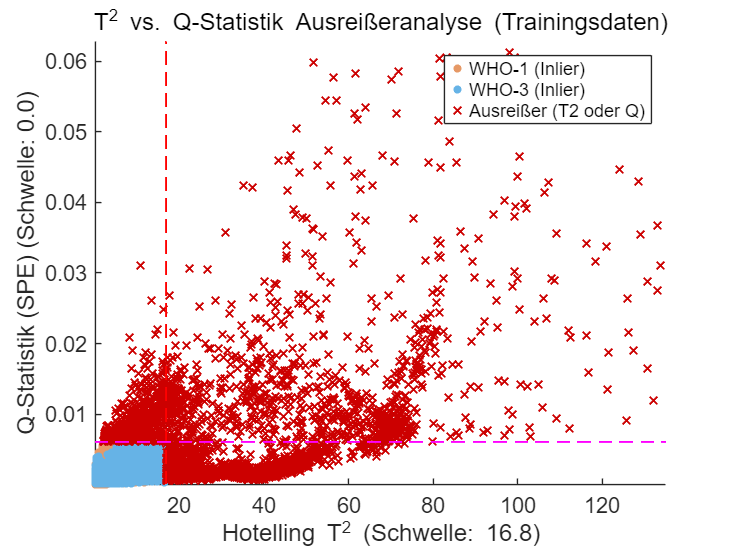

Figure 3 (T2 vs Q) saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\Phase1_Dissertation_Plots\20250517_P1_Fig3_T2vsQ_Outliers.tiff


Generating Figure 4: PCA Score Plot with Outliers...


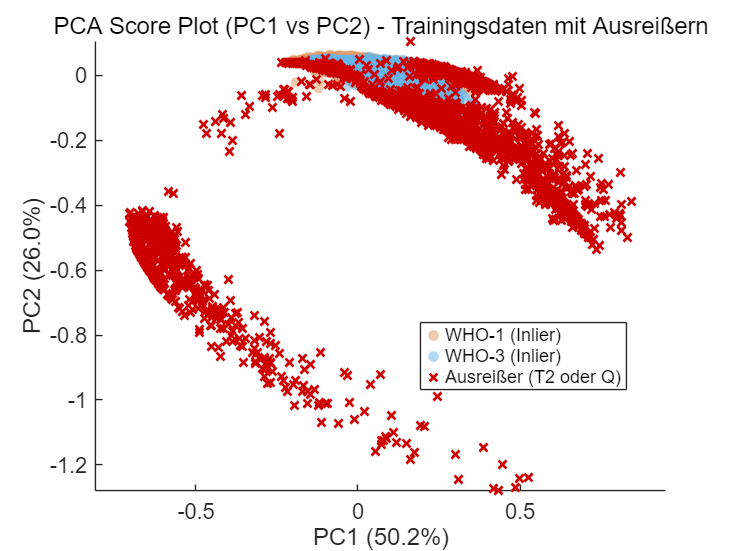

Figure 4 (PCA Scores) saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\Phase1_Dissertation_Plots\20250517_P1_Fig4_PCAscores_Outliers.tiff


Generating Figure 5: Patient-wise Outlier Spectra Overview...


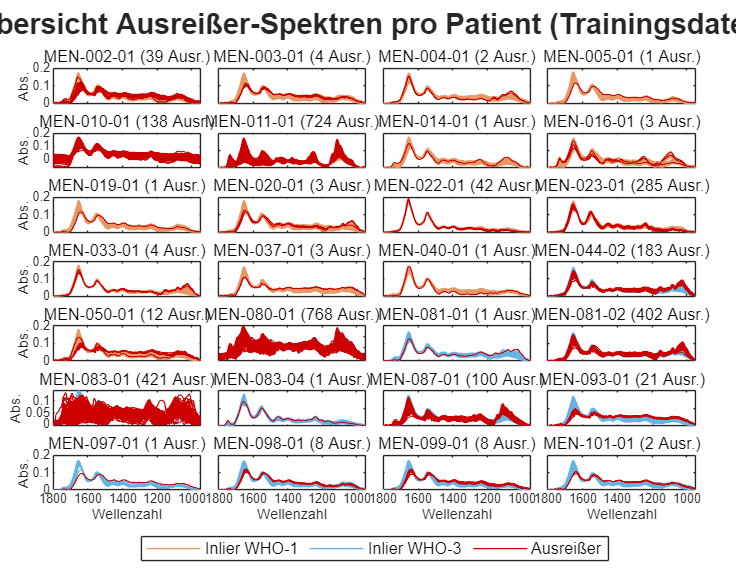

Figure 5 (Patient Outlier Overview) saved to: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\Phase1_Dissertation_Plots\20250517_P1_Fig5_PatientOutlierOverview.tiff



if outlier_plots_data_ready % Only proceed if data loading was successful
    % --- FIGURE 3: T2 vs Q Outlier Plot ---
    % (Plotting code for Fig 3 - from previous response, ensure vars match _plot suffix)
    fprintf('Generating Figure 3: T2 vs Q Outlier Plot...\n');
    fig3_handle = figure('Name', 'T2 vs Q Ausreißerplot (Trainingsdaten vor Bereinigung)');
    fig3_handle.Position = [100,100,800,600];
    hold on;
    non_outliers_p3 = ~outlier_indices_logical_plot; 
    isWHO1_non_outlier_p3 = (y_for_pca_plots == 1) & non_outliers_p3;
    isWHO3_non_outlier_p3 = (y_for_pca_plots == 3) & non_outliers_p3;
    h_f3 = []; leg_text_f3 = {};
    if any(isWHO1_non_outlier_p3), h_f3(end+1) = plot(T2_values_plot(isWHO1_non_outlier_p3), Q_values_plot(isWHO1_non_outlier_p3), 'o', 'Color', colorWHO1, 'MarkerSize', 4, 'MarkerFaceColor', colorWHO1); leg_text_f3{end+1} = 'WHO-1 (Inlier)'; end
    if any(isWHO3_non_outlier_p3), h_f3(end+1) = plot(T2_values_plot(isWHO3_non_outlier_p3), Q_values_plot(isWHO3_non_outlier_p3), 'o', 'Color', colorWHO3, 'MarkerSize', 4, 'MarkerFaceColor', colorWHO3); leg_text_f3{end+1} = 'WHO-3 (Inlier)'; end
    if any(outlier_indices_logical_plot), h_f3(end+1) = plot(T2_values_plot(outlier_indices_logical_plot), Q_values_plot(outlier_indices_logical_plot), 'x', 'Color', colorOutlier, 'MarkerSize', 6, 'LineWidth', 1); leg_text_f3{end+1} = 'Ausreißer (T2 oder Q)'; end
    yL_f3 = get(gca,'YLim'); xL_f3 = get(gca,'XLim');
    plot([T2_threshold_plot, T2_threshold_plot], yL_f3, 'Color', 'r', 'LineStyle', '--', 'LineWidth', 1, 'HandleVisibility','off');
    plot(xL_f3, [Q_threshold_plot, Q_threshold_plot], 'Color', 'm', 'LineStyle', '--', 'LineWidth', 1, 'HandleVisibility','off');
    hold off;
    xlabel(['Hotelling T^2 (Schwelle: ' num2str(T2_threshold_plot,'%.1f') ')'], 'FontSize', plotFontSize); 
    ylabel(['Q-Statistik (SPE) (Schwelle: ' num2str(Q_threshold_plot,'%.1f') ')'], 'FontSize', plotFontSize);
    title('T^2 vs. Q-Statistik Ausreißeranalyse (Trainingsdaten)', 'FontSize', plotFontSize+2, 'FontWeight','normal');
    if ~isempty(h_f3), legend(h_f3, leg_text_f3, 'Location', 'NorthEast', 'FontSize', plotFontSize-2); end
    grid off; set(gca, 'FontSize', plotFontSize);
    xlim_max_T2_f3 = prctile([T2_values_plot; T2_threshold_plot*1.1], 99.8); 
    ylim_max_Q_f3 = prctile([Q_values_plot; Q_threshold_plot*1.1], 99.8);   
    if xlim_max_T2_f3 > T2_threshold_plot && xlim_max_T2_f3 > min(T2_values_plot), xlim([min(T2_values_plot(T2_values_plot>0)) xlim_max_T2_f3]); else xlim('auto'); end
    if ylim_max_Q_f3 > Q_threshold_plot && ylim_max_Q_f3 > min(Q_values_plot), ylim([min(Q_values_plot(Q_values_plot>0)) ylim_max_Q_f3]); else ylim('auto'); end

    figName_P1_F3 = fullfile(figuresPath, sprintf('%s_P1_Fig3_T2vsQ_Outliers.tiff', dateStrForFilenames));
    exportgraphics(fig3_handle, figName_P1_F3, 'Resolution', 300); fprintf('Figure 3 (T2 vs Q) saved to: %s\n', figName_P1_F3); savefig(fig3_handle, strrep(figName_P1_F3, '.tiff', '.fig'));

    % --- FIGURE 4: PCA Score Plot (PC1 vs PC2) with Outliers Highlighted ---
    if exist('score_otl','var') && size(score_otl,2) >=2 && exist('explained_otl','var')
        fprintf('Generating Figure 4: PCA Score Plot with Outliers...\n');
        fig4_handle = figure('Name', 'PCA Score Plot mit Ausreißern (Trainingsdaten vor Bereinigung)');
        fig4_handle.Position = [150,150,800,600];
        hold on;
        non_outliers_p4 = ~outlier_indices_logical_plot;
        isWHO1_non_outlier_p4 = (y_for_pca_plots == 1) & non_outliers_p4;
        isWHO3_non_outlier_p4 = (y_for_pca_plots == 3) & non_outliers_p4;
        h_f4 = []; leg_text_f4 = {};
        if any(isWHO1_non_outlier_p4), h_f4(end+1) = scatter(score_otl(isWHO1_non_outlier_p4, 1), score_otl(isWHO1_non_outlier_p4, 2), 30, colorWHO1, 'o','filled', 'MarkerFaceAlpha',0.5); leg_text_f4{end+1} = 'WHO-1 (Inlier)'; end
        if any(isWHO3_non_outlier_p4), h_f4(end+1) = scatter(score_otl(isWHO3_non_outlier_p4, 1), score_otl(isWHO3_non_outlier_p4, 2), 30, colorWHO3, 'o','filled', 'MarkerFaceAlpha',0.5); leg_text_f4{end+1} = 'WHO-3 (Inlier)'; end
        if any(outlier_indices_logical_plot), h_f4(end+1) = scatter(score_otl(outlier_indices_logical_plot, 1), score_otl(outlier_indices_logical_plot, 2), 40, colorOutlier, 'x', 'LineWidth', 1.5); leg_text_f4{end+1} = 'Ausreißer (T2 oder Q)'; end
        hold off;
        xlabel(['PC1 (' num2str(explained_otl(1), '%.1f') '%)'], 'FontSize', plotFontSize);
        ylabel(['PC2 (' num2str(explained_otl(2), '%.1f') '%)'], 'FontSize', plotFontSize);
        title('PCA Score Plot (PC1 vs PC2) - Trainingsdaten mit Ausreißern', 'FontSize', plotFontSize+2, 'FontWeight','normal');
        if ~isempty(h_f4), legend(h_f4, leg_text_f4, 'Location', 'best', 'FontSize', plotFontSize-2); end
        axis equal; grid off; set(gca, 'FontSize', plotFontSize);
        figName_P1_F4 = fullfile(figuresPath, sprintf('%s_P1_Fig4_PCAscores_Outliers.tiff', dateStrForFilenames));
        exportgraphics(fig4_handle, figName_P1_F4, 'Resolution', 300); fprintf('Figure 4 (PCA Scores) saved to: %s\n', figName_P1_F4); savefig(fig4_handle, strrep(figName_P1_F4, '.tiff', '.fig'));
    else
        fprintf('Skipping Figure 4 (PCA Score Plot) due to missing PCA score data or <2 PCs.\n');
    end
    
    % --- FIGURE 5: Patient-wise Outlier Spectra Overview ---
    % (Plotting code for Fig 5 - from previous response, ensure vars match _for_outlier_plots suffix)
    if exist('X_train_for_outlier_plots','var') && exist('Patient_ID_train_for_outlier_plots','var') && exist('y_train_cat_for_outlier_plots','var')
        fprintf('Generating Figure 5: Patient-wise Outlier Spectra Overview...\n');
        unique_pids_plot5 = unique(Patient_ID_train_for_outlier_plots);
        patients_with_outliers_info_plot5 = {};
        for i_p5 = 1:length(unique_pids_plot5)
            current_pid_p5 = unique_pids_plot5{i_p5};
            pid_indices_p5 = find(strcmp(Patient_ID_train_for_outlier_plots, current_pid_p5)); if isempty(pid_indices_p5); continue; end
            pid_outlier_status_p5 = outlier_indices_logical_plot(pid_indices_p5);
            num_pid_outliers_p5 = sum(pid_outlier_status_p5);
            if num_pid_outliers_p5 > 0
                pid_who_grade_p5 = y_train_cat_for_outlier_plots(pid_indices_p5(1));
                patients_with_outliers_info_plot5{end+1,1} = {current_pid_p5, num_pid_outliers_p5, pid_who_grade_p5};
            end
        end
        patient_plot_count_p5 = size(patients_with_outliers_info_plot5, 1);
        if patient_plot_count_p5 > 0
            nrows_layout_p5 = 7; ncols_layout_p5 = 4; total_tiles_p5 = nrows_layout_p5 * ncols_layout_p5;
            if patient_plot_count_p5 > total_tiles_p5, fprintf('INFO: Fig5 showing first %d patients with outliers.\n', total_tiles_p5); end
            fig5_handle = figure('Name', 'Patienten-Ausreißer Übersicht (7x4 Layout)', 'Position', [50, 50, 1100, 850]);
            tl_p5 = tiledlayout(nrows_layout_p5, ncols_layout_p5, 'TileSpacing', 'tight', 'Padding', 'compact');
            title(tl_p5, 'Übersicht Ausreißer-Spektren pro Patient (Trainingsdaten)', 'FontSize', plotFontSize+4, 'FontWeight', 'bold');
            lw_non_outlier_p5 = 0.5; lw_outlier_p5 = 0.7; alpha_non_outlier_p5 = 0.25;
            fs_subplot_title_p5 = 9; fs_subplot_axlabel_p5 = 8; fs_subplot_ticklabel_p5 = 7;
            h_legend_elements_p5 = gobjects(3,1); legend_texts_p5 = {'Inlier WHO-1', 'Inlier WHO-3', 'Ausreißer'}; plotted_for_legend_p5 = [false, false, false];
            for i_p5_plot = 1:min(patient_plot_count_p5, total_tiles_p5)
                current_patient_data_p5 = patients_with_outliers_info_plot5{i_p5_plot};
                current_patient_id_p5 = current_patient_data_p5{1}; num_outliers_for_patient_p5 = current_patient_data_p5{2}; patient_who_grade_p5 = current_patient_data_p5{3};
                ax_p5 = nexttile(tl_p5); hold(ax_p5, 'on'); box(ax_p5, 'on');
                pid_indices_plot = find(strcmp(Patient_ID_train_for_outlier_plots, current_patient_id_p5));
                pid_spectra_all_plot = X_train_for_outlier_plots(pid_indices_plot, :); pid_outlier_status_plot = outlier_indices_logical_plot(pid_indices_plot);
                pid_spectra_outliers = pid_spectra_all_plot(pid_outlier_status_plot, :); pid_spectra_non_outliers = pid_spectra_all_plot(~pid_outlier_status_plot, :);
                color_pid_non_outlier = ([0.5 0.5 0.5]); legend_idx_norm = 0;
                if patient_who_grade_p5 == 'WHO-1', color_pid_non_outlier = colorWHO1; legend_idx_norm = 1; elseif patient_who_grade_p5 == 'WHO-3', color_pid_non_outlier = colorWHO3; legend_idx_norm = 2; end
                if ~isempty(pid_spectra_non_outliers)
                    for k_spec=1:size(pid_spectra_non_outliers,1), plot(ax_p5, wavenumbers_roi, pid_spectra_non_outliers(k_spec,:), 'Color', [color_pid_non_outlier, alpha_non_outlier_p5], 'LineWidth', lw_non_outlier_p5, 'HandleVisibility','off'); end
                    if legend_idx_norm > 0 && ~plotted_for_legend_p5(legend_idx_norm) && size(pid_spectra_non_outliers,1)>0, h_legend_elements_p5(legend_idx_norm) = plot(ax_p5, NaN, NaN,'Color',[color_pid_non_outlier, alpha_non_outlier_p5],'LineWidth',lw_non_outlier_p5); plotted_for_legend_p5(legend_idx_norm) = true; end
                end
                if ~isempty(pid_spectra_outliers)
                    for k_spec=1:size(pid_spectra_outliers,1), plot(ax_p5, wavenumbers_roi, pid_spectra_outliers(k_spec,:), 'Color', [colorOutlier, 0.7], 'LineWidth', lw_outlier_p5, 'HandleVisibility','off'); end
                    if ~plotted_for_legend_p5(3) && size(pid_spectra_outliers,1)>0, h_legend_elements_p5(3) = plot(ax_p5, NaN, NaN,'Color',[colorOutlier,0.7],'LineWidth',lw_outlier_p5); plotted_for_legend_p5(3) = true; end
                end
                hold(ax_p5, 'off'); xlim(ax_p5, plotXLim); ylim(ax_p5, 'auto'); 
                set(ax_p5, 'XTickMode', 'auto', 'YTickMode', 'auto', 'FontSize', fs_subplot_ticklabel_p5);
                ax_p5.XDir = 'reverse'; grid(ax_p5, 'off');
                title(ax_p5, sprintf('%s (%d Ausr.)', current_patient_id_p5, num_outliers_for_patient_p5), 'FontSize', fs_subplot_title_p5, 'FontWeight','normal');
                current_tile_idx_p5 = get(ax_p5,'Layout').Tile;
                if mod(current_tile_idx_p5-1, ncols_layout_p5) == 0, ylabel(ax_p5, 'Abs.', 'FontSize', fs_subplot_axlabel_p5); else set(ax_p5, 'YTickLabel',[]); end
                if current_tile_idx_p5 > (nrows_layout_p5-1)*ncols_layout_p5, xlabel(ax_p5, 'Wellenzahl', 'FontSize', fs_subplot_axlabel_p5); else set(ax_p5, 'XTickLabel',[]); end
            end
            valid_legend_handles_p5 = h_legend_elements_p5(isgraphics(h_legend_elements_p5));
            valid_legend_texts_p5 = legend_texts_p5(isgraphics(h_legend_elements_p5));
            if ~isempty(valid_legend_handles_p5)
                lgd_p5 = legend(valid_legend_handles_p5, valid_legend_texts_p5, 'FontSize', plotFontSize-3, 'Orientation', 'horizontal'); % Use valid_legend_handles for legend command
                lgd_p5.Layout.Tile = 'South'; 
            end
            figName_P1_F5 = fullfile(figuresPath, sprintf('%s_P1_Fig5_PatientOutlierOverview.tiff', dateStrForFilenames));
            exportgraphics(fig5_handle, figName_P1_F5, 'Resolution', 300); fprintf('Figure 5 (Patient Outlier Overview) saved to: %s\n', figName_P1_F5); savefig(fig5_handle, strrep(figName_P1_F5, '.tiff', '.fig'));
        else
            fprintf('Skipping Figure 5 as no patients with outliers were found to plot.\n');
        end
    else
        fprintf('Skipping Figure 5 (Patient Outlier Overview) due to missing X_train_for_outlier_plots or Patient_ID_train_for_outlier_plots.\n');
    end
else
    fprintf('Skipping Figures 3, 4, 5 (Outlier Plots) as outlier_plots_data_ready is false.\n');
end


fprintf('\nPhase 1 plotting script finished.\n');


Phase 1 plotting script finished.
